# A Estimation curve VS different S_EI: Test LSY idea about using previous mV

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/zx555/Documents/MATLAB/NYU-Vision-main/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ConnectionMat(N_E,NnE,Size_E,...
                     N_E,NnE,Size_E,...
                     Peak_EE,SD_E,Dist_LB,1);

Elapsed time is 11.799881 seconds.



C_EI = ConnectionMat(N_E,NnE,Size_E,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,0);

Elapsed time is 4.570411 seconds.



C_IE = ConnectionMat(N_I,NnI,Size_I,...
                     N_E,NnE,Size_E,...
                     Peak_I,SD_E,Dist_LB,0);

Elapsed time is 4.093852 seconds.



C_II = ConnectionMat(N_I,NnI,Size_I,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,1);

Elapsed time is 1.490039 seconds.


## Variables and Parameters

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
load('Initials.mat')
%parameters
S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.029; S_EI = 0.055; S_IE = 0.0081; S_II = 0.048; %Tuned
%S_EE = 0.028; S_EI = 0.056; S_IE = 0.0095; S_II = 0.042; % original
p_EEFail = 0.2; S_amb = 0.01;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms
dt = 0.2;
gL_E = 1/20;  Ve = 14/3; S_Elgn = 0.059; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; S_Ilgn = 0.084; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 
rE_amb = 0.72; rI_amb = 0.36;

% Replace S_EI by testing values
S_EItest = 0.054:0.001:0.068;

## Test different stepsizes and LIF simu time

% defining cluster. Stepsizes and simu time I want to test
cluster = parpool([4 64]);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


cluster.IdleTimeout = 120;

htest = [1,0.5,0.1];
SimuTtest = [40 20 10]*1e3; % in ms

a = length(S_EItest);
b = length(htest);
c = length(SimuTtest);

Fr_NoFix_h_time_TestmV = zeros(2,a,b,c);
mV_NoFix_h_time_TestmV = zeros(2,a,b,c);
Fr_NoFixVar_h_time_TestmV = zeros(2,a,b,c);
mV_NoFixVar_h_time_TestmV = zeros(2,a,b,c);

Fr_NoFixVar_h_time_batch_TestmV  = zeros(2,a,b,c);
mV_NoFixVar_h_time_batch_TestmV  = zeros(2,a,b,c);

Fr_NoFixTraj_h_time_TestmV = cell(a,b,c);
mV_NoFixTraj_h_time_TestmV = cell(a,b,c);


loopCount_h_time_TestmV = zeros(a,b,c); % count the number of loops
ConvIndi_h_time_TestmV = logical(loopCount_h_time_TestmV);

SampleNum = 200;
MaxNum = 400;
BatchSize = 10; % for batch mean and standard error
BatchNum = floor(SampleNum/BatchSize);
%h = 0.1;
tic
for hInd = 1:b
    h = htest(hInd);
    for SimuTInd = 1:c
        SimuT = SimuTtest(SimuTInd);
        parfor S_EIInd = 1:length(S_EItest)
            S_EI = S_EItest(S_EIInd);
            tic
            [Fr_NoFixTraj_h_time_TestmV{S_EIInd,hInd,SimuTInd},mV_NoFixTraj_h_time_TestmV{S_EIInd,hInd,SimuTInd},...
                loopCount_h_time_TestmV(S_EIInd,hInd,SimuTInd),    ConvIndi_h_time_TestmV(S_EIInd,hInd,SimuTInd)]...
                ...
                  = MeanFieldEst_BkGd_Indep_StepSize_TestmV(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,...
                                            'End',SampleNum,MaxNum,h,SimuT);
                                        
            toc
       end
    end
end

Elapsed time is 18.994008 seconds.
Elapsed time is 18.818188 seconds.
Elapsed time is 18.782014 seconds.
Elapsed time is 20.279741 seconds.
Elapsed time is 20.292900 seconds.
Elapsed time is 21.628222 seconds.
Elapsed time is 17.081794 seconds.
Elapsed time is 17.083888 seconds.
Elapsed time is 17.250175 seconds.
Elapsed time is 16.623959 seconds.
Elapsed time is 18.993120 seconds.
Elapsed time is 20.523074 seconds.
Elapsed time is 10.025682 seconds.
Elapsed time is 11.397024 seconds.
Elapsed time is 10.219429 seconds.
Elapsed time is 8.991413 seconds.
Elapsed time is 9.894439 seconds.
Elapsed time is 9.458715 seconds.
Elapsed time is 11.083740 seconds.
Elapsed time is 12.015938 seconds.
Elapsed time is 12.235223 seconds.
Elapsed time is 10.039030 seconds.
Elapsed time is 8.567703 seconds.
Elapsed time is 10.159057 seconds.
Elapsed time is 12.028529 seconds.
Elapsed time is 11.215655 seconds.
Elapsed time is 11.747122 seconds.
Elapsed time is 6.724057 seconds.
Elapsed time is 8.183257 

toc

Elapsed time is 291.300713 seconds.



% mean and var
for hInd = 1:b
    for SimuTInd = 1:c
        for S_EIInd = 1:a
            Fr_NoFix_h_time_TestmV(:,S_EIInd,hInd,SimuTInd) = mean(Fr_NoFixTraj_h_time_TestmV{S_EIInd,hInd,SimuTInd}(:,end-SampleNum:end),2);
            mV_NoFix_h_time_TestmV(:,S_EIInd,hInd,SimuTInd) = mean(mV_NoFixTraj_h_time_TestmV{S_EIInd,hInd,SimuTInd}(:,end-SampleNum:end),2);
            Fr_NoFixVar_h_time_TestmV(:,S_EIInd,hInd,SimuTInd) = var(Fr_NoFixTraj_h_time_TestmV{S_EIInd,hInd,SimuTInd}(:,end-SampleNum:end),0,2);
            mV_NoFixVar_h_time_TestmV(:,S_EIInd,hInd,SimuTInd) = var(mV_NoFixTraj_h_time_TestmV{S_EIInd,hInd,SimuTInd}(:,end-SampleNum:end),0,2);
        end
    end
end

% batch. We get batch variation to estimate the square of MC standard error
for hInd = 1:b
    for SimuTInd = 1:c
        for S_EIInd = 1:a
            Fr_Sample = reshape(Fr_NoFixTraj_h_time_TestmV{S_EIInd,hInd,SimuTInd}(:,end-SampleNum+1:end),2,BatchSize,BatchNum);
            mV_Sample = reshape(mV_NoFixTraj_h_time_TestmV{S_EIInd,hInd,SimuTInd}(:,end-SampleNum+1:end),2,BatchSize,BatchNum);
            
            Fr_NoFixVar_h_time_batch_TestmV(:,S_EIInd,hInd,SimuTInd) = var(squeeze(mean(Fr_Sample,2)),0,2)/BatchNum;
            mV_NoFixVar_h_time_batch_TestmV(:,S_EIInd,hInd,SimuTInd) = var(squeeze(mean(mV_Sample,2)),0,2)/BatchNum;
        end
    end
end    

## Compare hs/SimuTs for single trajectories

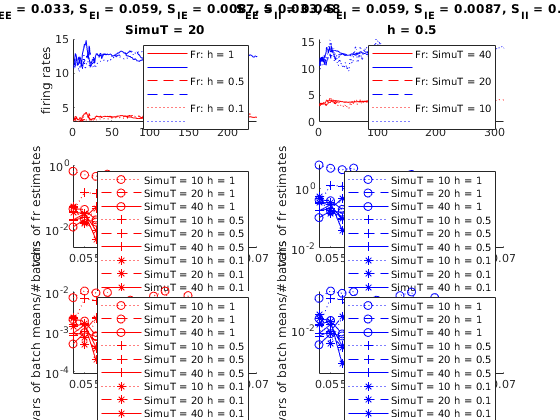

figure('Name','Compare hs/SimuTs for single trajectories')
% Same SimuT, different h
subplot 321
StestInd = 6; SimuTInd = 2;
LineType = {'-','--',':'};
hold on
for hInd = 1:b
plot(Fr_NoFixTraj_h_time_TestmV{StestInd,hInd,SimuTInd}(1,:),'r','LineStyle',LineType{hInd},...
                                                          'DisplayName',['Fr: h = ' num2str(htest(hInd))])
plot(Fr_NoFixTraj_h_time_TestmV{StestInd,hInd,SimuTInd}(2,:),'b','LineStyle',LineType{hInd},...
                                                          'DisplayName','')
end
hold off
title({['S_{EE} = ' num2str(S_EE) ', S_{EI} = ' num2str(S_EItest(StestInd)) ...
                         ', S_{IE} = ' num2str(S_IE) ', S_{II} = ' num2str(S_II)],...
                                       ['SimuT = ' num2str(SimuTtest(SimuTInd)/1e3)]})
legend                                   
ylabel('firing rates')                  

% Same h, different SimuT
subplot 322
StestInd = 6; hInd = 2;
LineType = {'-','--',':'};
hold on
for SimuTInd = 1:c
plot(Fr_NoFixTraj_h_time_TestmV{StestInd,hInd,SimuTInd}(1,:),'r','LineStyle',LineType{SimuTInd},...
                                                          'DisplayName',['Fr: SimuT = ' num2str(SimuTtest(SimuTInd)/1e3)])
plot(Fr_NoFixTraj_h_time_TestmV{StestInd,hInd,SimuTInd}(2,:),'b','LineStyle',LineType{SimuTInd},...
                                                          'DisplayName','')
end
hold off
title({['S_{EE} = ' num2str(S_EE) ', S_{EI} = ' num2str(S_EItest(StestInd)) ...
                         ', S_{IE} = ' num2str(S_IE) ', S_{II} = ' num2str(S_II)],...
                                       ['h = ' num2str(htest(hInd))]})
legend


%varQuot1 = Fr_NoFixVar_h/Fr_NoFixVar; 
subplot 323
LineType = {'-','--',':'};
MarkerType = {'o','+','*'};
hold on
for hInd = 1:b
    for SimuTInd = c:-1:1
        plot(S_EItest,Fr_NoFixVar_h_time_TestmV(1,:,hInd,SimuTInd),'r',...
             'LineStyle',LineType{SimuTInd}, 'Marker',MarkerType{hInd},...
             'DisplayName',['SimuT = ' num2str(SimuTtest(SimuTInd)/1e3) ' h = ' num2str(htest(hInd))])
    end
end
hold off
legend
set(gca,'YScale','log')
ylabel('vars of fr estimates')

subplot 324
LineType = {'-','--',':'};
MarkerType = {'o','+','*'};
hold on
for hInd = 1:b
    for SimuTInd = c:-1:1
        plot(S_EItest,Fr_NoFixVar_h_time_TestmV(2,:,hInd,SimuTInd),'b',...
             'LineStyle',LineType{SimuTInd}, 'Marker',MarkerType{hInd},...
             'DisplayName',['SimuT = ' num2str(SimuTtest(SimuTInd)/1e3) ' h = ' num2str(htest(hInd))])
    end
end
hold off
legend
set(gca,'YScale','log')
ylabel('vars of fr estimates')

% batch var for MC standard error
subplot 325
LineType = {'-','--',':'};
MarkerType = {'o','+','*'};
hold on
for hInd = 1:b
    for SimuTInd = c:-1:1
        plot(S_EItest,Fr_NoFixVar_h_time_batch_TestmV(1,:,hInd,SimuTInd),'r',...
             'LineStyle',LineType{SimuTInd}, 'Marker',MarkerType{hInd},...
             'DisplayName',['SimuT = ' num2str(SimuTtest(SimuTInd)/1e3) ' h = ' num2str(htest(hInd))])
    end
end
hold off
legend
set(gca,'YScale','log')
ylabel('vars of batch means/#batchs')

subplot 326
LineType = {'-','--',':'};
MarkerType = {'o','+','*'};
hold on
for hInd = 1:b
    for SimuTInd = c:-1:1
        plot(S_EItest,Fr_NoFixVar_h_time_batch_TestmV(2,:,hInd,SimuTInd),'b',...
             'LineStyle',LineType{SimuTInd}, 'Marker',MarkerType{hInd},...
             'DisplayName',['SimuT = ' num2str(SimuTtest(SimuTInd)/1e3) ' h = ' num2str(htest(hInd))])
    end
end
hold off
legend
set(gca,'YScale','log')
ylabel('vars of batch means/#batchs')